# **IO3xx A2B - Loopback**

This example demonstrates the A2B code module and the A2B IO3xx extension hardware functionalities using an A2B Setup block (**A2B Setup v1)**, two A2B TDM write blocks (**A2B I2S/TDM Write v1)**, two A2B TDM read blocks (**A2B I2S/TDM Read v1)** and an A2B Status block (**A2B Status v1)***,* which are all connected to a loopback on the same I/O module. You can test the basic functionality of the A2B code modules and the IO3xx extension by running this loopback test. 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed (Note: not IO30x or IO31x)

- One IO3xx_40 interface extension installed (containing 2x A2B physical transceivers)

- A Speedgoat configuration file that supports the IO3xx_40 interface extension (using the required A2B functionality, and the connections to the A2B physical transceivers)

- A2B connection wire

- SigmaStudio™ by Analog Devices - in case you want to change the A2B configuration

### Test Setup

In this example, data is sent from Node1 (A2B Main) to Node2 (A2B SubNode) and vice versa. You must therefore connect the B-Port 1 (MainNode Downstream) to the A-Port 2 (SubNode Upstream) on the IO3xx_40.

                         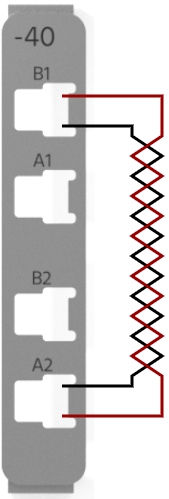

## Initialize and Open the Simulink model

 
modelName = 'sgMdl_IO3xx_40_A2B_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io3xx) block, as this example can be executed on different configurable I/O modules. First, open the mask of the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io3xx) block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

### Select I/O module and set configuration file

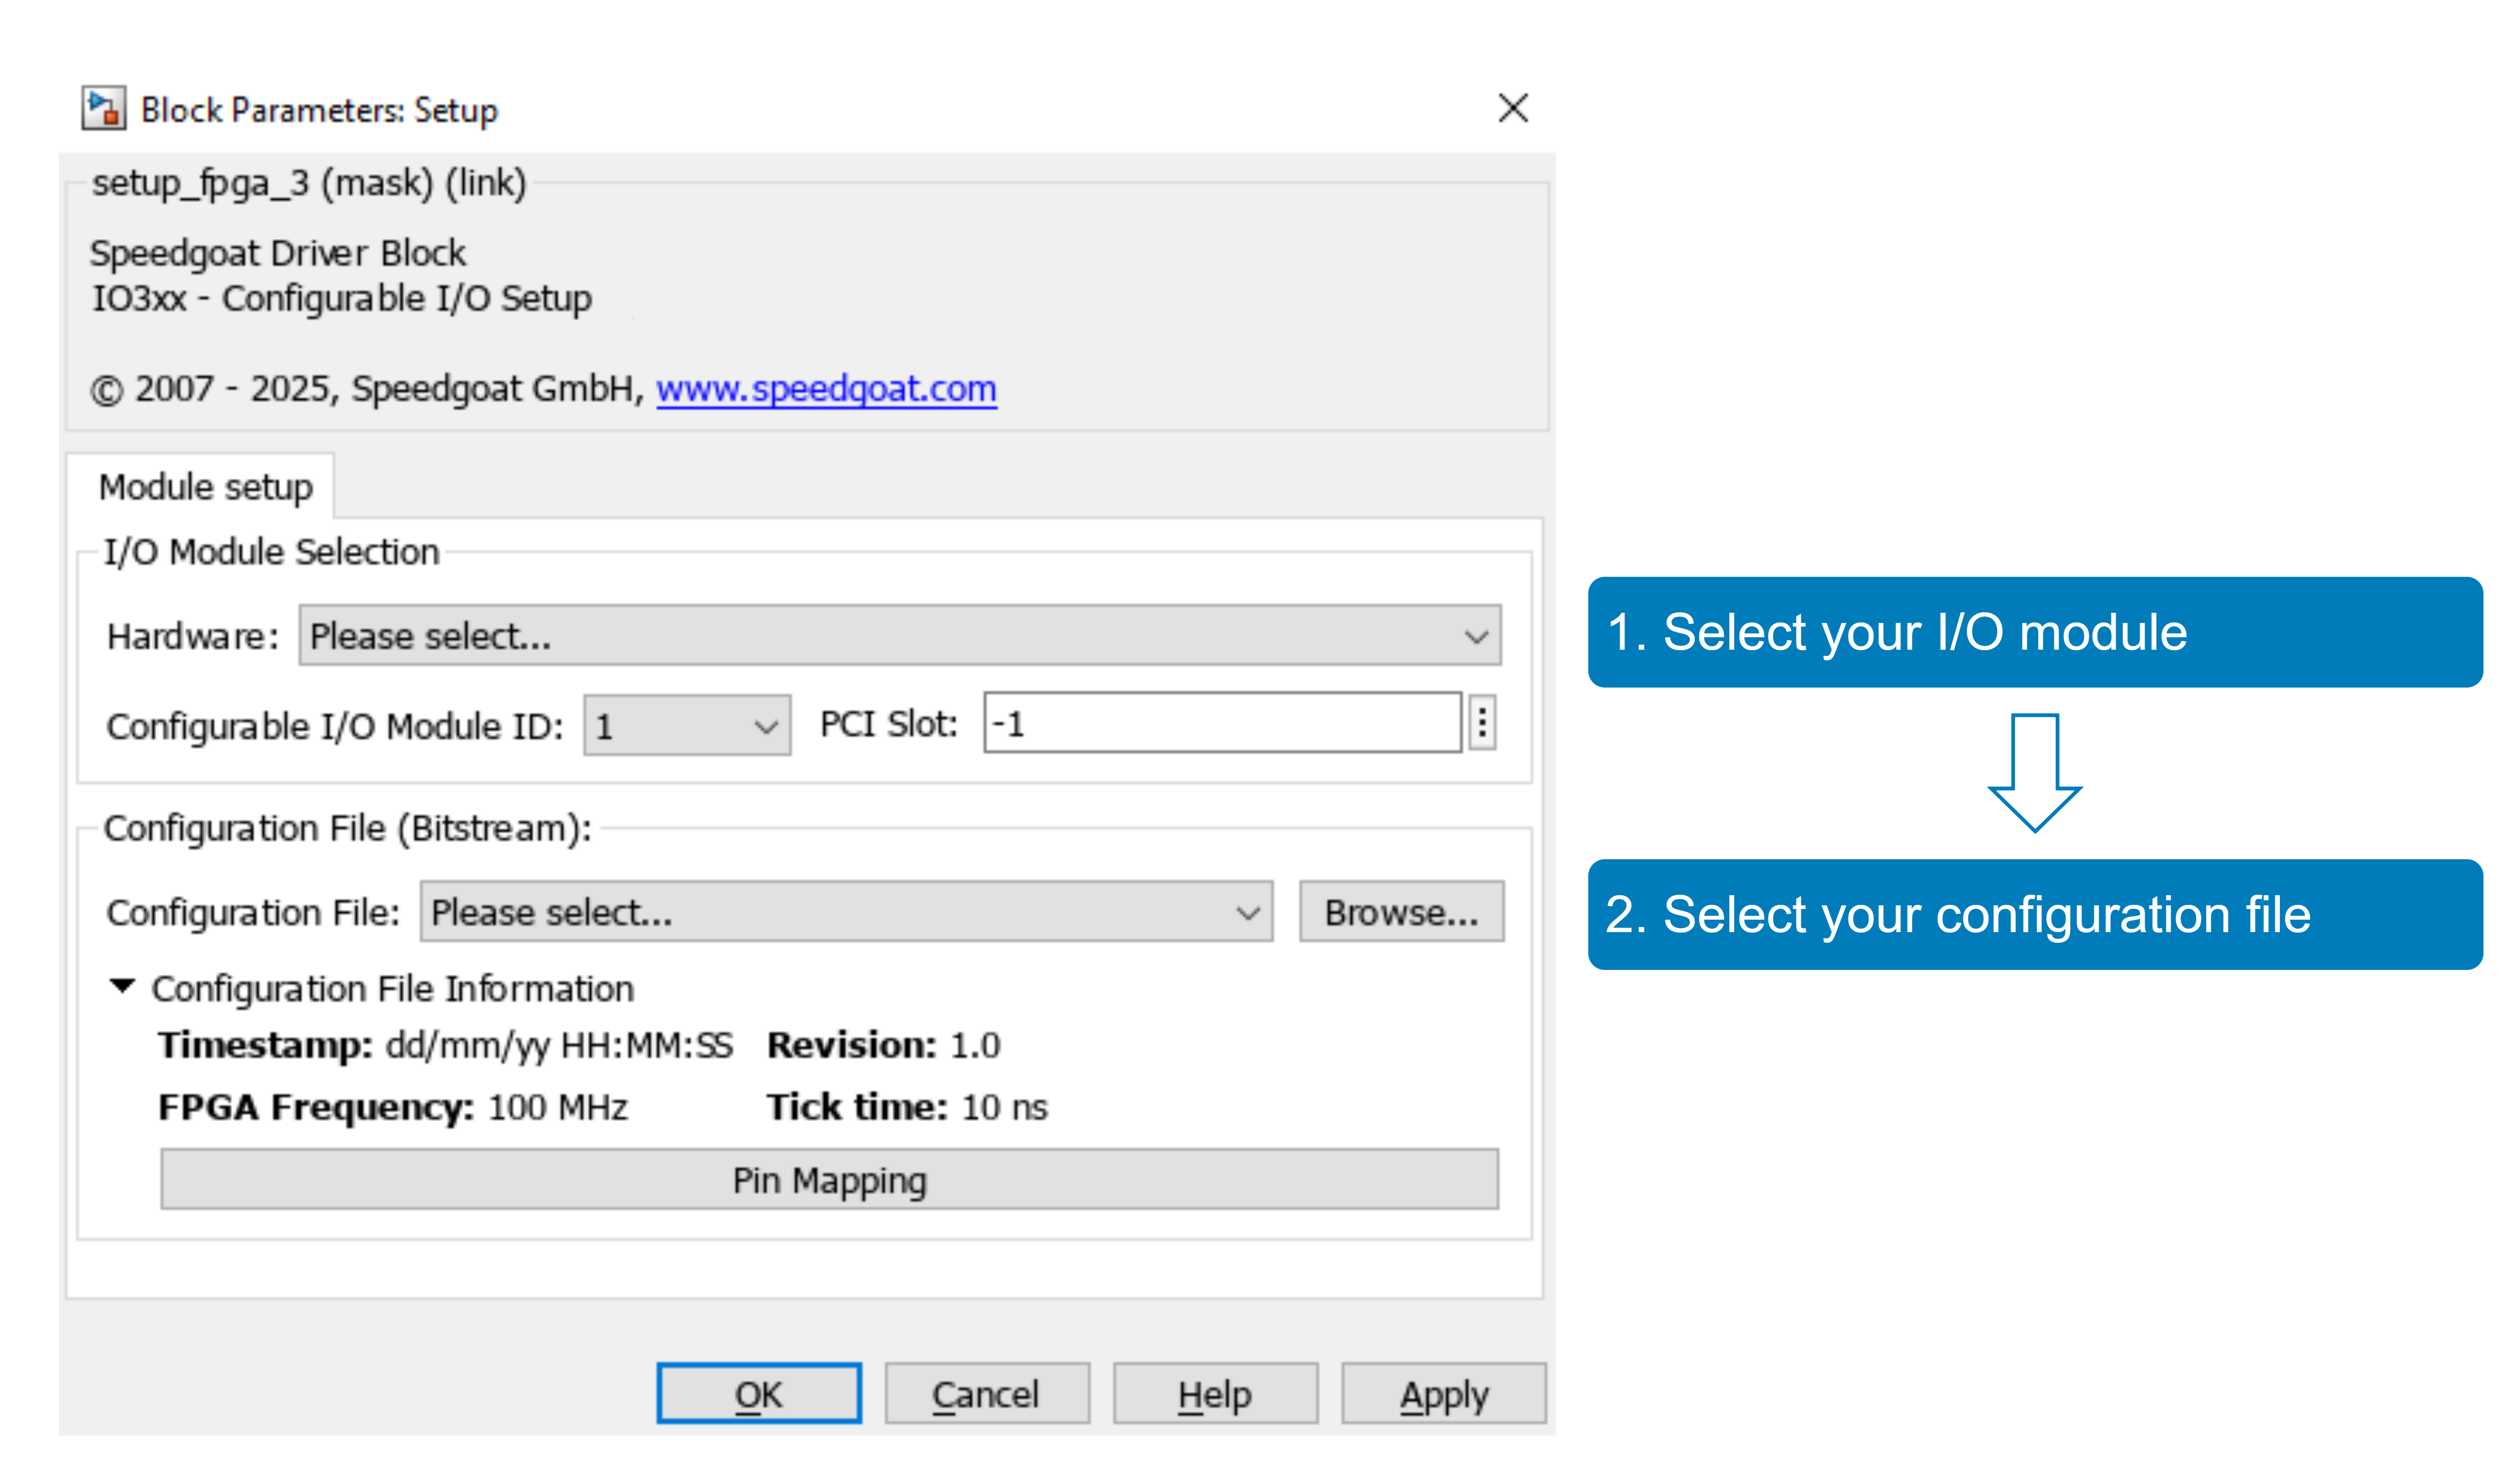

Click the **Pin Mapping** button to check where the functionalities are located.

### Ensure the IO3xx_40 (A2B I/O-Extension) is Enabled

In the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io3xx) block, ensure the -40 (A2B I/O interface extension) is enabled:

You can also enable the Rear-IO using the following command:

 
set_param([modelName, '/Setup'], 'rearEnb_1', 'on');

### Ensure Optimize Data Transfer is Enabled and DMA Trigger Source is Set to "A2B"

In the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io3xx) block, ensure the **Optimize Data Transfer** is controlled by your selected IO3xx module. This is mandatory when the A2B I/O interface extension is used. The DMA trigger must be set to A2B source:

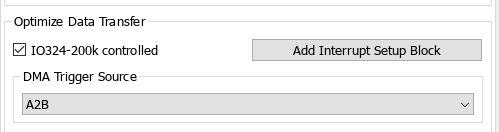

You can also set these options using the following command:

 
set_param([modelName, '/Setup'], 'useFpgaDmaController', 'on');
set_param([modelName, '/Setup'], 'dmaTrigDropdown', 'A2B');

**NOTE:**

Using **Optimize Data Transfer** requires the model to be triggered by an interrupt. The model for this product example already contains an Interrupt Setup block. The next steps explain how to set up this block.

By selecting the A2B as the trigger source, the A2B Frame Rate will be automatically used to set the model rate. For more details, refer to the Data Framing and Timing chapter below.

### Set Up the Interrupt Source

After setting up the I/O module, open the Speedgoat [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block and click the **Select Interrupt** button. In the window that opens, select the interrupt with your I/O module appended with **FPGA polling**. Then, select **Use as Model Trigger** and **Use in Polling Mode** to ensure the model for this example runs correctly.

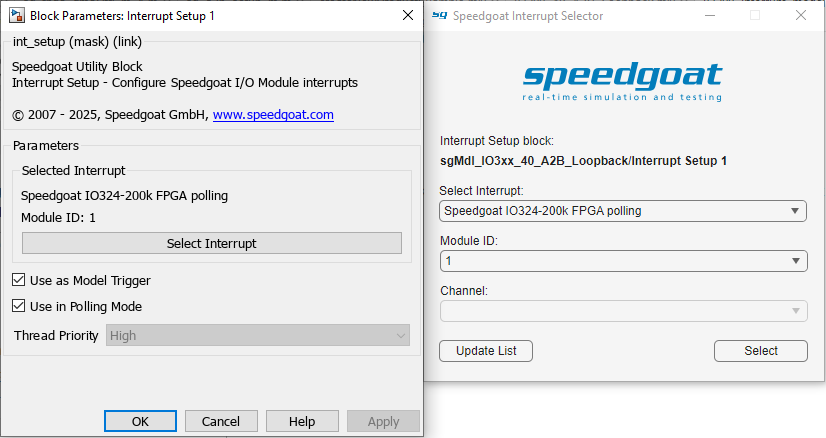

## Model Description

### A2B Setup

The IO3xx-40 (A2B) rear IO contains two A2B physical transceivers. This model already contains configuration files (prepared using SigmaStudio™) to run the 1st A2B transceiver as a MainNode Unit, and the 2nd transceiver as a SubNode Unit.

The following image shows the complete setup (including hardware) of this example model. As a user, only the **Model **part is relevant. While the other parts are for information only, they are nonetheless helpful, especially in showing how the A2B data is handled in the model.

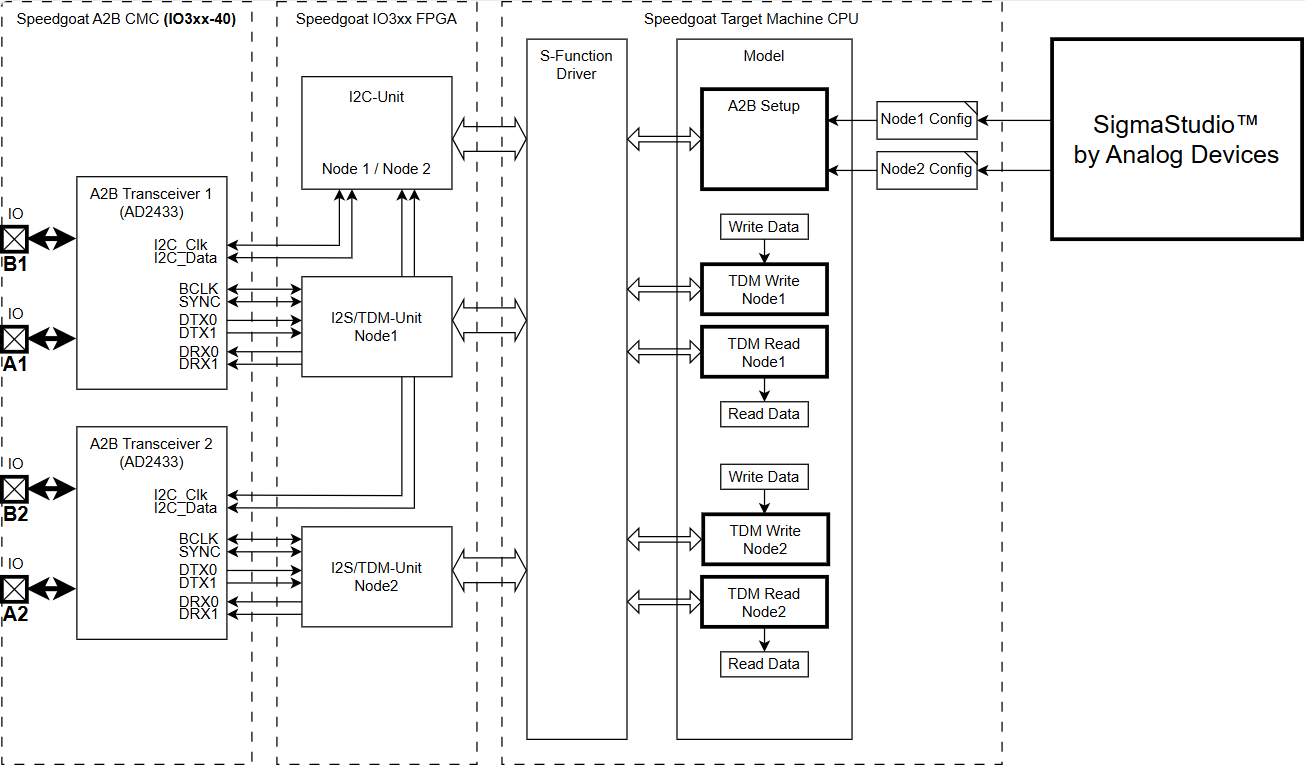

The IO3xx_40 (and its drivers) is designed to handle a wide range of different TDM configurations. The configuration files of this example model are generated as follows:

#### MainNode Configuration:

- **TDM Mode**: TDM16 (note that the IO3xx_40 implementation contains two TDM channels, meaning there are 32 TDM channels in total; 2x16)

- **Upstream & Downstream Slots**: 16 Slots, with a 24-bit data size

- **TDM Channel Size**: 32 bit. This setting is required due to the 24-bit data size in the A2B data slots mentioned above

#### SubNode Configuration:

- **TDM Mode**: TDM16 (note that the IO3xx_40 implementation contains two TDM-channels, meaning there are 32 TDM channels in total; 2x16)

- **TDM Channel Size**: 32 bit. This setting is required due to the 24-bit data size in the A2B data slots mentioned above

#### Mandatory Settings on the A2B Node Configurations:

The integration of the A2B transceivers on the IO3xx_40 requires the following mandatory settings:

- **Rx0, Rx1, Tx0, Tx1** must be enabled

- **Rx Interleave, Tx Interleave** must be enabled

- **Sync Polarity, DRXn Sampling BCLK, DTXn Change BCLK** must be Rising Edge

Open the **IO3xx_40_A2B_Loopback.dspproj** file attached in SigmaStudio™ to obtain all the details of the network and node configurations for this example model.

The settings required for the correct A2B configuration are implemented in the [A2B Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_setup) Block. On the **Main **tab, **A2B1** must be set to MainNode, and **A2B2** must be set to Subordinate Node. Furthermore, the **Frame Size** for this example model must be set to 4 (for more details, refer to the Data Framing and Timing chapter). The **Configuration File** for the network (networkConfig.dat) and for the MainNode (mainNodeConfig.xml) must be set in the **A2B1** tab. The **Configuration File** for the SubNode (subNodeConfig.xml) must be set in the **A2B2** tab. You can either select the configuration files using the corresponding **Browse** buttons, or run the following lines:

 
set_param([modelName, '/A2B Setup '], 'parNetworkConfig1', ['''', which('networkConfig.dat'), '''']);
set_param([modelName, '/A2B Setup '], 'parNodeConfig1', ['''', which('mainNodeConfig.xml'), '''']);
set_param([modelName, '/A2B Setup '], 'parNodeConfig2', ['''', which('subNodeConfig.xml'), '''']);

**NOTE**: 

If the configuration file changes (e.g., if you changed the configuration using SigmaStudio™), then you need to update the configuration files manually. This can be done by clicking the **Update** button in the **A2B1** and **A2B2** tabs, or by running the following lines:

 
A2BSetupBlockObj = Simulink.Mask.get([modelName, '/A2B Setup ']);
UpdateCallBack = A2BSetupBlockObj.getDialogControl('btnUpdateNode1').Callback();
eval(strrep(UpdateCallBack, ');', ', ''block'', [modelName, ''/A2B Setup '']);'));
UpdateCallBack = A2BSetupBlockObj.getDialogControl('btnUpdateNode2').Callback();
eval(strrep(UpdateCallBack, ');', ', ''block'', [modelName, ''/A2B Setup '']);'));

### A2B TDM Write/Read

The [A2B I2S/TDM Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_write) blocks are used to write data from the model to the A2B transceivers. The [A2B I2S/TDM Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_read) Blocks are used to read data received from the A2B transceivers. The numbers on the inputs represent the corresponding TDM-Slot + 1 on the TDM interface. Depending upon the A2B configuration, this data is inserted into the A2B stream. The configuration files for this example model are a 1:1 map between the TDM Interface and the A2B stream. This means for read and write, TDM-Slot 0 is read and written to/from Slot0 of the A2B Stream, TDM-Slot 1 is read and written to/from Slot1 of the A2B Stream and so on.

#### TDM Used/Active Channels

In this example model, the TDM interface for the Main and the SubNode are configured to TDM16, and there are 2 TDM interfaces per A2B transceiver. Consequently, there are 32 TDM channels in total. 

The A2B stream is configured to 16 down and 16 up slots. TDM channels 16-31 are therefore not mapped to the A2B stream. They are present on the [A2B I2S/TDM Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_write) and [A2B I2S/TDM Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_read) blocks, but they do not serve any purpose.

The [A2B Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_setup) block gets all this information from the corresponding configuration files, and then distributes the corresponding settings to the other A2B blocks.

#### Data Width

In this example model, the A2B down- and upstream is set to 24 bits. Note that the [A2B I2S/TDM Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_write) and [A2B I2S/TDM Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_read) blocks always implement TDM-data signals of type uint32. The underlying block functionality will always use the minimum number of bits required. This means that the [A2B I2S/TDM Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_write) block ignores the higher range bits (bits 24 to 31 in this example model), while the [A2B I2S/TDM Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_read) block zero fills the upper bits (bits 24 to bit 31 in this example model). For this reason, the data is bit-masked before the comparison

Note that the **A2B Data Size [Bits]** in a configuration file for a SubNode is not available. Consequently, the [A2B Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_setup) block cannot distribute the corresponding settings. The **A2B Data Size [Bits]** must therefore be manually set to 24 in the  [A2B I2S/TDM Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_write) and [A2B I2S/TDM Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_i2stdm_read) blocks for the SubNode.

### Data Framing and Timing

The A2B communication functions as the sample trigger of this model, ensuring fully synchronized TDM data reading and writing. In the [IO3xx Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io3xx) block, enable **Optimize Data Transfer** and set **DMA Trigger Source** to **A2B**.

In this example model, the A2B Audio Clock is configured to 48 kHz, resulting in a model execution rate of 48 kHz. The [A2B Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_a2b_setup) block can be used to set a **Frame Size** (set to 4 in this example model) to slow down the model trigger rate (e.g. 48 kHz/4 = 12 kHz in this example model). The write and read data therefore are vector signals, where each vector element represents a value from the corresponding frame-part.

The following image shows the timing of the example model, TDM transfer, and also the transfer on A2B:

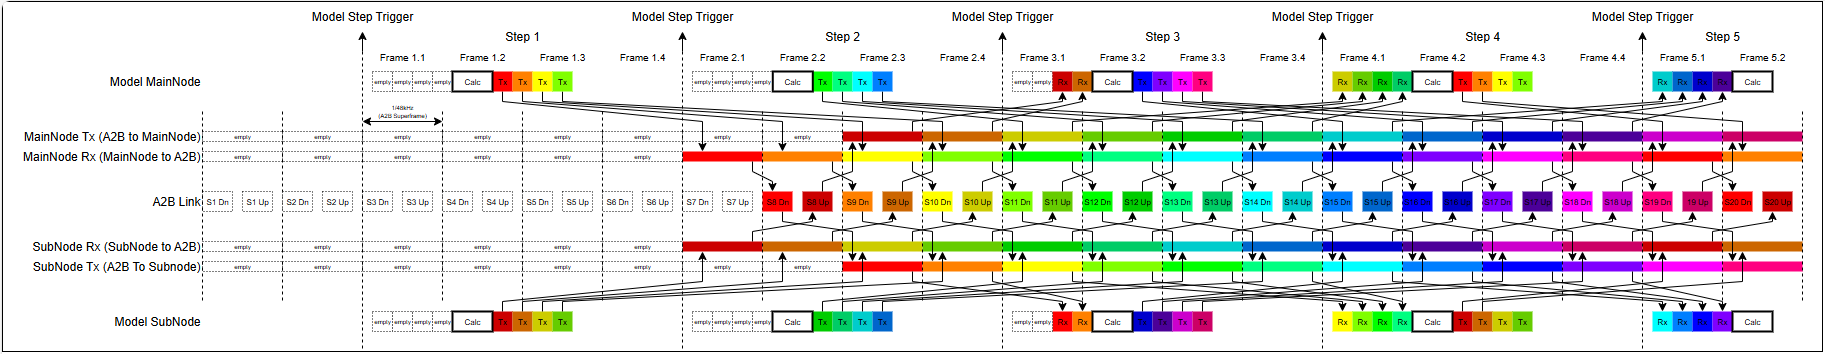

After the model has started, the MainNode starts transferring empty (zero) values and triggers the first step. Note that one frame of data in the model is equal to four A2B superframes.

#### Step 1:

- The model reads the TDM-Rx Data (MainNode and SubNode) that is still empty (zero values)

- The model calculates Tx values (to be sent from the MainNode to the SubNode and vice versa)

- The model writes the Tx values to the IO3xx_40 TDM Interface (MainNodeRx and SubNodeRx)

- The TDM interfaces and the A2B Link are still empty (zero values)

#### Step 2:

- The model reads the TDM-Rx Data (MainNode and SubNode) that is still empty (zero values)

- The model calculates Tx values (to be sent from the MainNode to the SubNode and vice versa)

- The model writes the Tx values to the IO3xx_40 TDM-Interface

- The TDM interfaces transfer the Tx values from the previous model step (Frame1) to the A2B transceivers (through MainNodeRx and SubNodeRx)

- The A2B Link buffers the TDM values (from MainNodeRx and SubNodeRx) and transfers them on A2B with one A2B superframe delay

- The A2B Link receives A2B values that can be read on the TDM interface (MainNodeTx and SubNodeTx) with another A2B superframe delay

- The TDM interfaces read the values from the A2B transceivers (using MainNodeRx and SubNodeRx)

#### Step 3:

- The model gets the TDM-Rx Data (MainNode and SubNode). Due to the buffer behavior of the IO3xx_40 and the A2B transceivers, the four parts of the frame are as follows:

- *    Rx-Data Frame Part1 = Empty*

- *    Rx-Data Frame Part2 = Empty*

- *    Rx-Data Frame Part3 = Tx-Data Frame Part1 of Step1*

- *    Rx-Data Frame Part4 = Tx-Data Frame Part2 of Step1*

- Other parts as per Step 2

#### Step 4:

- The model gets the TDM-Rx Data (MainNode and SubNode). Due to the buffer behavior of the IO3xx_40 and the A2B transceivers, the four parts of the frame are as follows:

- *    Rx-Data Frame Part1 = Tx-Data Frame Part3 of Step1*

- *    Rx-Data Frame Part2 = Tx-Data Frame Part4 of Step1*

- *    Rx-Data Frame Part3 = Tx-Data Frame Part1 of Step2*

- *    Rx-Data Frame Part4 = Tx-Data Frame Part2 of Step2*

- Other parts as per Step 2

### Data Generation and Check

This example model uses a simple increasing counter to generate the Tx data from Main to SubNode and vice versa. To uniquely identify each TDM channel and also each part of the frame, different offsets are added to each TDM channel and each Frame-part.

In the **Check Data** area, the timing latency between the data transmitted and received is aligned, and each data element (of each TDM channel and each part of the frame) is compared. If all the data match, the MainToSub_OK and SubToMain_OK signals are HIGH.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

## Check the Results

To check if the loopback is working as expected, open the Simulink scope connected to the following signals:

### Data Check

- ScopeDataGood/MainToSub_OK: Shows if all the data is correctly transferred from Main to SubNode

- ScopeDataGood/SubToMain_OK: Shows if all the data is correctly transferred from Sub to MainNode

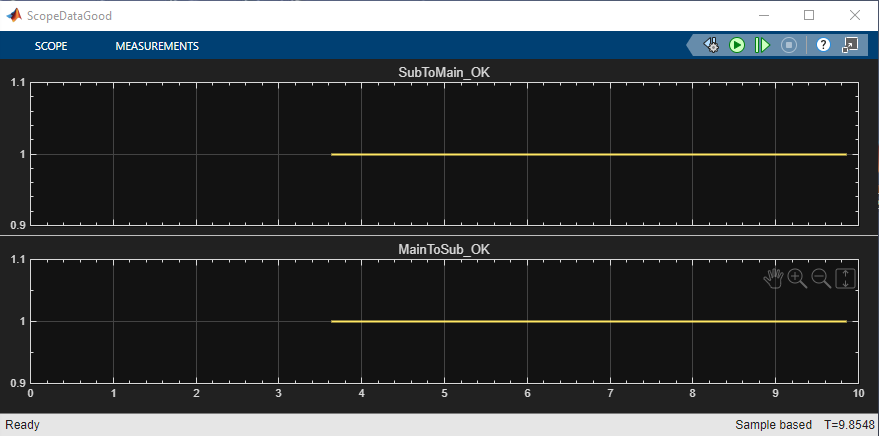

- MainToSub_OK is 1 (all the data transferred on MainNode was correctly received on SubNode)

- SubToMain_OK is 1 (all the data transferred on SubNode was correctly received on MainNode)

### A2B Status

- ScopeStatus/Status: Shows the status of the A2B MainNode

- ScopeStatus/Node: Shows the affected A2B SubNode in case a failure occurs

- ScopeStatus/LineFault: Shows the type of Line Fault

- ScopeStatus/Disc: Shows if the A2B Network was successfully discovered

- ScopeStatus/ReDisc: Shows the number of Re-Discovery attempts

- ScopeStatus/NumSubs: Shows the number of A2B SubNodes connected

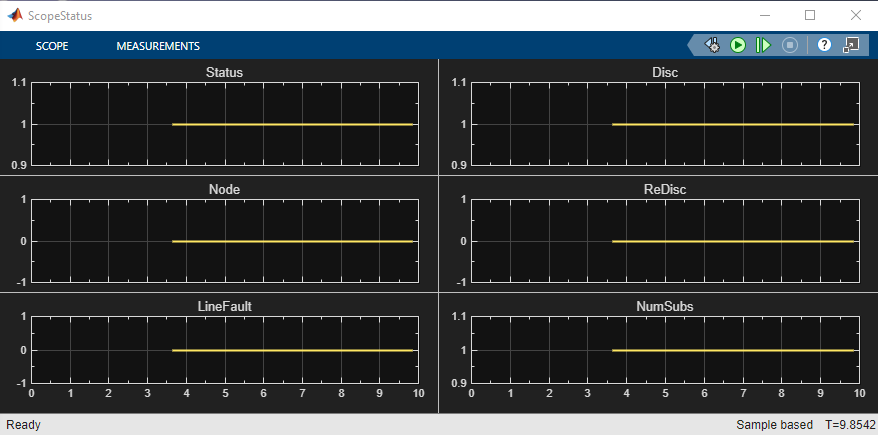

- Status is 1 (A2B Network is ok)

- Node is 0 (No Node with an issue)

- Line Fault is 0 (No issues detected)

- Discovery is 1 (A2B network is discovered)

- Redisc is 0 (A2B network re-discovery was not required)

- NumSubs is 1 (One A2B SubNode is present in the A2B network)

## Additional References

- [A2B (GPIO v1, I2C v1, Setup v1, Status v1, TDM Read v1, TDM Write v1) and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_a2b)

[](https://www.speedgoat.com/help/slrt/page/io_main/refentry_quadrature_usage_notes)